# Loop shaping example #2

Consider the following plant


$$G(s) = \frac{2(1+s)}{(1+10s)(1+s\tau)}$$


whose output is measured by a sensor whose transfer function is


$$H(s) = \frac{0.1}{1+0.2s}$$


The parameter $\tau$ is uncertain and is in the range $[0, 0.04] $s.

Design a controller that satisfies the following requirements

- steady-state relative error $e_{\infty r} \le 5\%$ for $r(t)=R_0 \mathbf{1} (t)$

- steady-state relative error $e_{\infty r} \le 5\%$ for a disturbance in the range $\omega \in \left[ 0.01, 0.5 \right]$ rad/s

- steady-state relative error $e_{\infty r} \le 0.1\%$ for a reference signal in the range $\omega \in \left[ 0, 1 \right]$ rad/s

- attenuation of at least -20dB for a noise in the range $\omega \in \left[ 50, 100 \right]$rad/s

- phase margin $\varphi_M > 30\degree $

## Control requirements

The requirements can be expressed as follows:

- the steady state error requires $\mu = 1$ and a static gain of $L(s)$ of at least 100

- the requirement on the rejection on a multi-frequency disturbance yields $|L(i\omega)|_{dB} \ge 26$dB in $ \omega \in \left[ 0.01, 0.5 \right]$

- the requirement on the tracking of a multi-frequency reference signal yields $|L(i\omega)|_{dB} \ge 20$dB in $ \omega \in \left[ 0, 1 \right]$

- the requirement on the attenuation of a multi-frequency noise signal yields $|L(i\omega)|_{dB} \le -20$dB in $ \omega \in \left[ 50, 100 \right]$

- the phase margin requirement can be left unchanged

## Solution

Define system's transfer function

s = tf('s');
H = 0.1/(1+0.2*s);
G1 = (2*(1+s)) / ((1+10*s)*(1+0.04*s)); % tau=0.04
G2 = (2*(1+s)) / ((1+10*s)*(1+0*s));    % tau=0

Choose K1 to satisfy steady-state requirements

K1 = 100/s;

Choose K2 for transient performance (zero + lead-network)

K2 = ((1+10*s)*(1+0.05*s))/(1+s);

Verify requirements

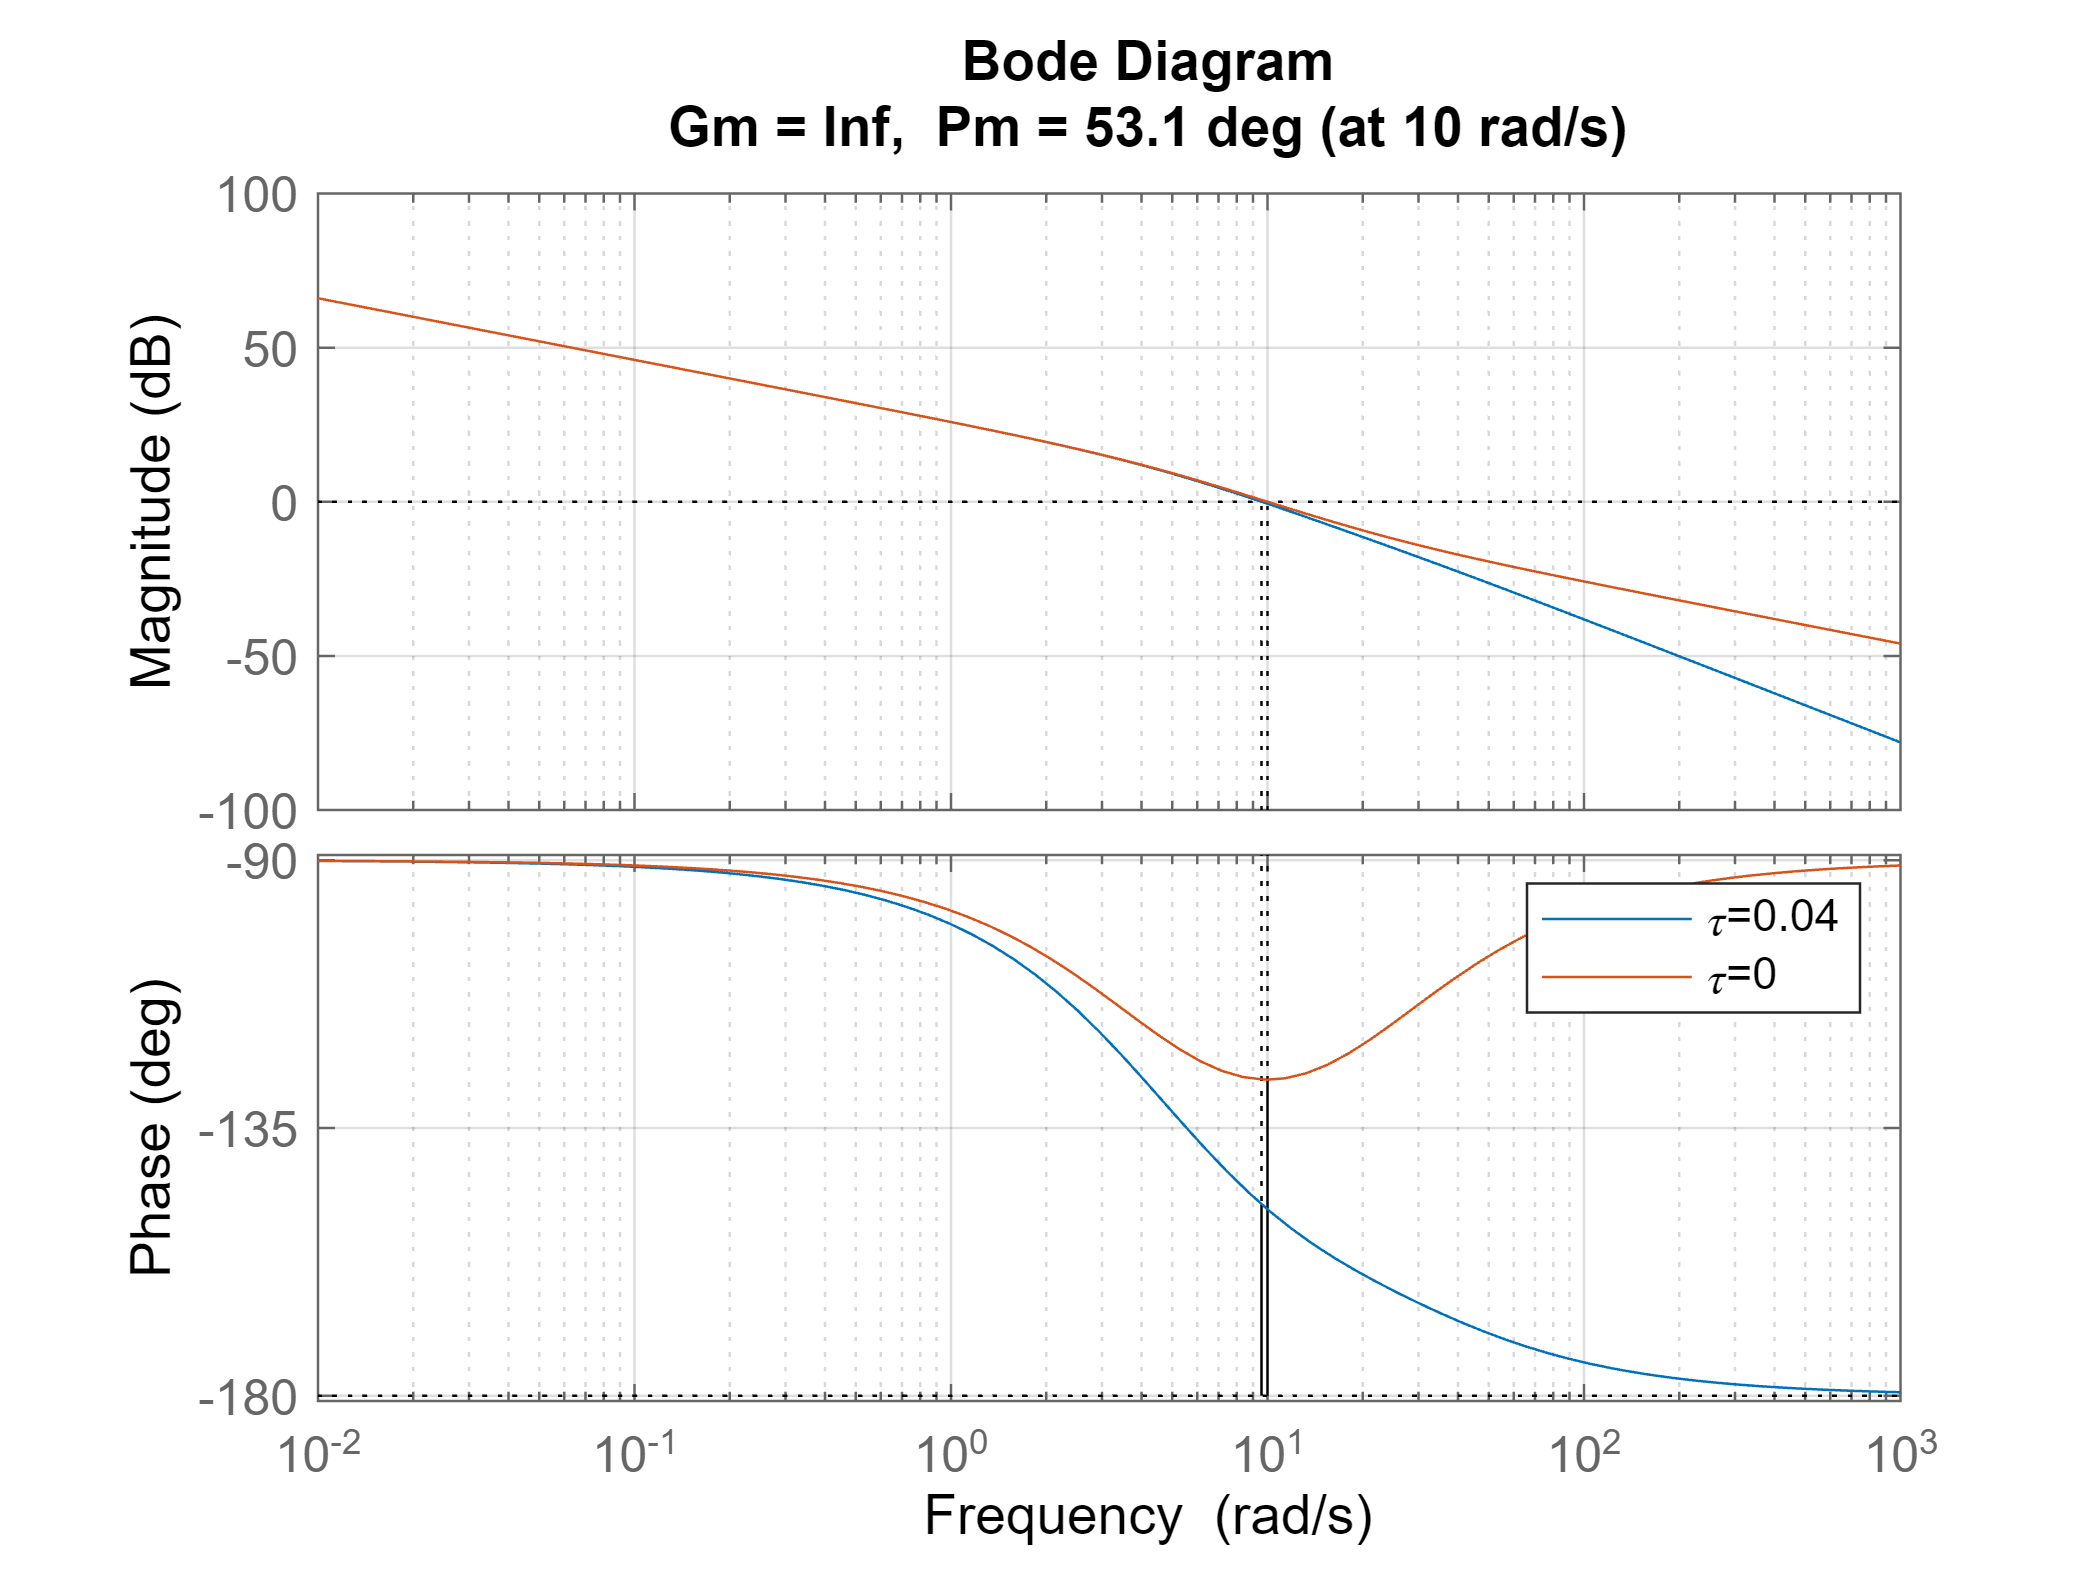

L1 = K1*K2*G1*H; % tau=0.04
L2 = K1*K2*G2*H; % tau=0

margin(L1)
grid on, hold on
margin(L2)
legend('\tau=0.04','\tau=0')